# Tarjeta de audio

## Escanear dispositivos de audio

audioInfo=audiodevinfo

audioInfo = struct with fields:
     input: [1×3 struct]
    output: [1×2 struct]


## Crear el objeto de audio

Id=-1;
fs=44100;
CH_No=1;
BitDepth=16;
recordObject=audiorecorder(fs,BitDepth,CH_No,Id)

recordObject =   audiorecorder with properties:

       SampleRate: 44100
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


## Grabación

T=3;
recordblocking(recordObject,T);

## Ploteo

data_grabacion=getaudiodata(recordObject);
%Vector de tiempo
%Ts=1/fs
t=1/fs:1/fs:T

t =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011


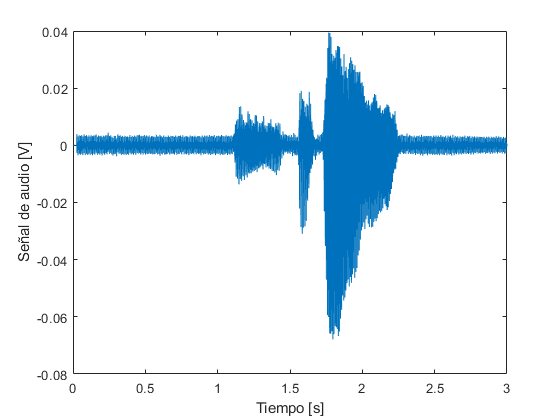

plot(t,data_grabacion)
xlabel("Tiempo [s]")
ylabel("Señal de audio [V]")

## Reproducción

sound(data_grabacion,2*fs)

## Espectro

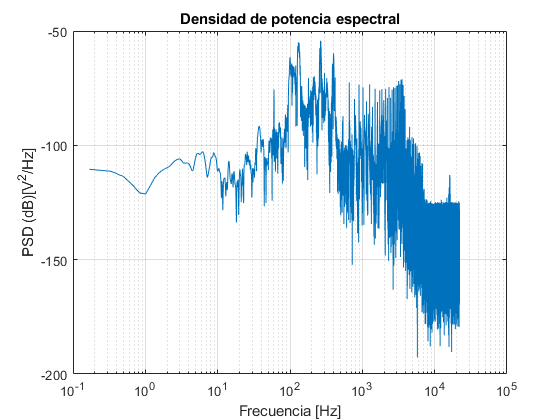

%Parámetros importantes
N=numel(data_grabacion);
N_spect=N/50;
%Funciones de descomposición espectral
[Pxx_per,F_Pxx]=periodogram(data_grabacion,rectwin(N),[],fs);
[~,F_Spec,T_Spec,Pxx_Spec]=spectrogram(data_grabacion,rectwin(N_spect),[],[],fs);
%Periodograma
figure
semilogx(F_Pxx,10*log10(Pxx_per))
title("Densidad de potencia espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD (dB)[V^2/Hz]")
grid on

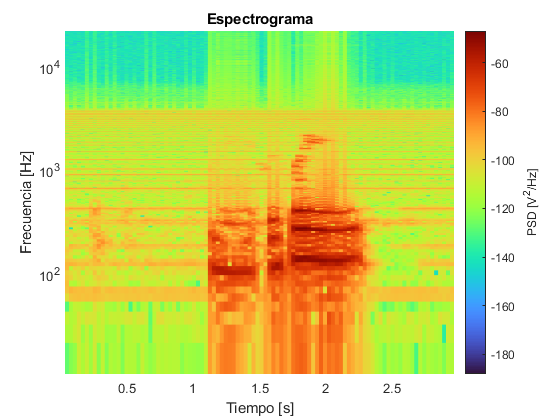

%Espectrograma
figure
p=pcolor(T_Spec,F_Spec,10*log10(Pxx_Spec));
set(p,'EdgeColor','none')
xlabel("Tiempo [s]")
ylabel("Frecuencia [Hz]")
title("Espectrograma")
c=colorbar;
c.Label.String="PSD [V^2/Hz]";
colormap('turbo')

set(gca,'YScale','log')

## Guardar audio

audiowrite("voz.wav",data_grabacion,fs)